# System Integration 

This live notebook will cover the system integration techniques used for the [2024 RoboCup ARM Challenge](https://2024.robocup.org/join-the-autonomous-robot-manipulation-arm-challenge/). Within this notebook, we will dive into the following key components:

- **Overview**: An overview of the workflow and pseudocode detailing the process.

- **Vision**: Techniques used to accurately map the environment.

- **Motion Planning**: Methods used to determine the precise position and orientation of the robot and objects within the environment.

Sections of this notebook were inspired by the MATLAB's[ "Pick-and-Place Workflow in Gazebo Using Point-Cloud Processing and RRT Path Planning"](https://www.mathworks.com/help/robotics/ug/pick-and-place-gazebo-with-point-clouds-and-rrt.html) documented example code. This notebook is especially written for Lipscomb University students to understand system integration for the robotics challenge. The content covered within this notebook is high-level and does not require intermediate knowledge of all sections of the code. Instead, this high-level understanding should be used by team leaders to foresee issues or steps required for motion planning, vision, and maximizing achievable points. 

## Section 1 - Overview

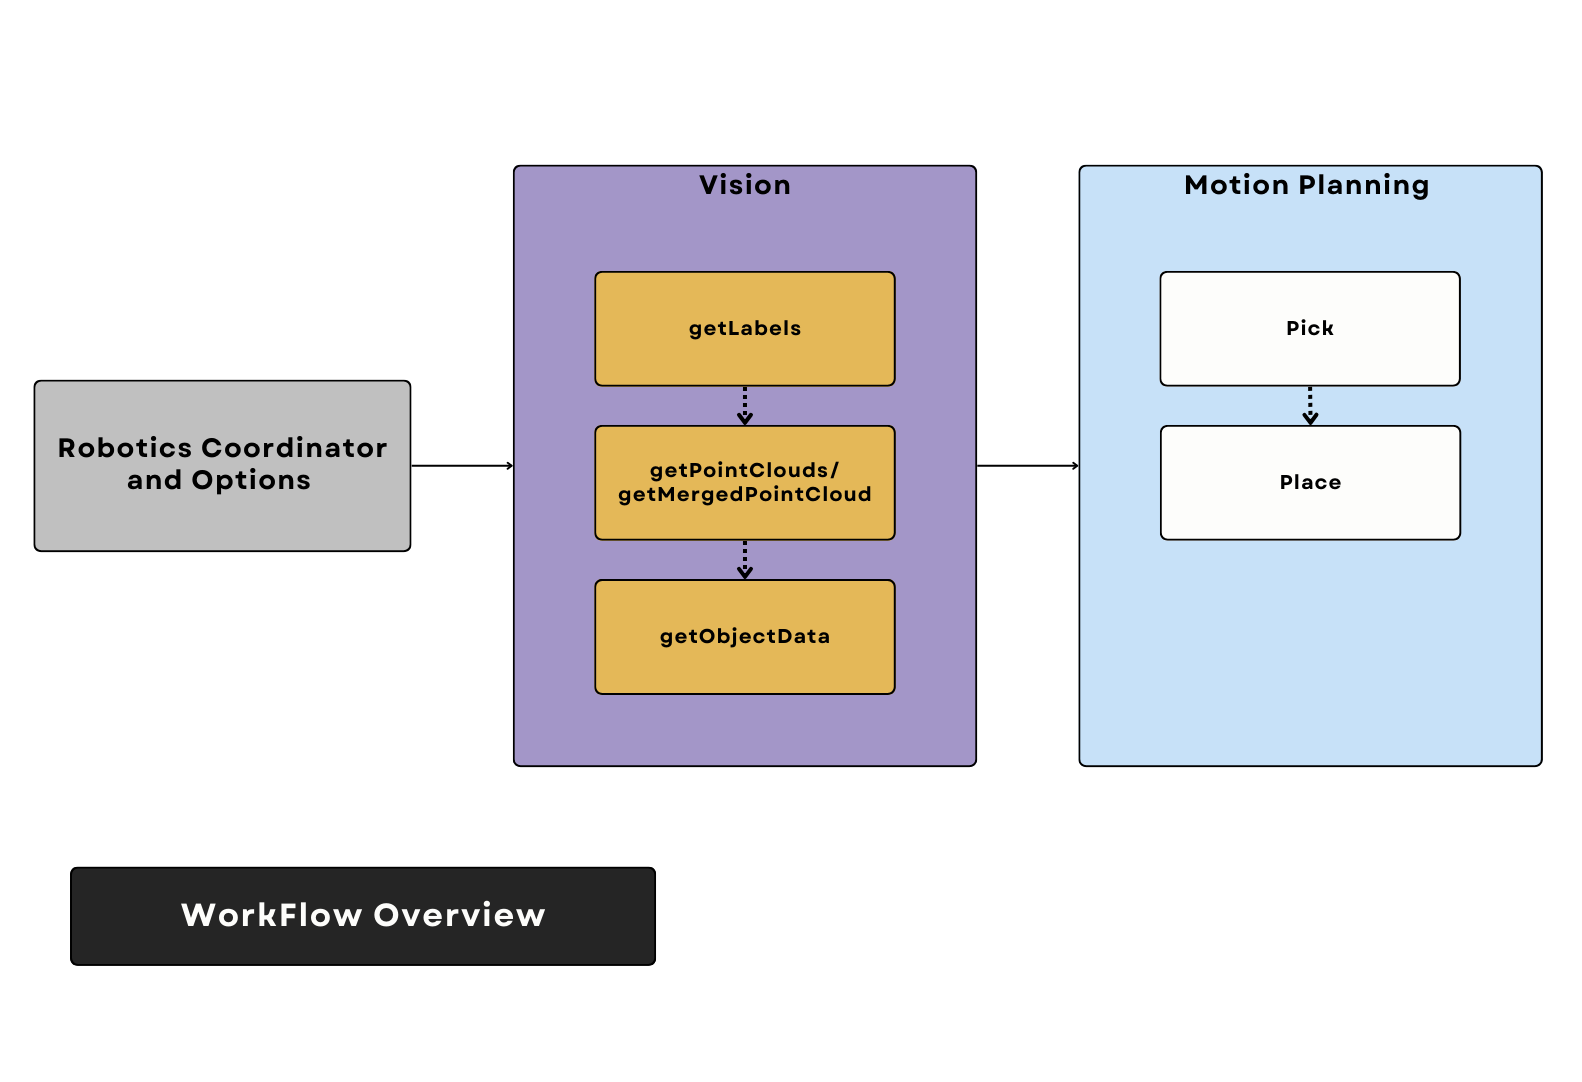

The image above demonstrates an abstracted flow chart that will help in understanding the actions taken within each section of the code. The flow chart comprises the following parts:

- **robotCoordinator and Options (optns)**: In this initialization section of the code, the Robotics Operating System (ROS) will be initialized using `rosinit()`. A dictionary of options will be created, containing flags or variables that can assist in debugging and provide extra options to functions or operations. It is good practice to contain all this information within a class handle to set up ROS communications with Gazebo and control the pick-and-place workflow. This will hold information about ROS-MATLAB communications, such as subscribers, publishers, action clients, etc. This will also store data for easy access, such as the robot's rigidBodyTree for visualizations, robot end effector names, robot joint configurations, number of joints, and more. Note that anything requiring loading should be kept within the class handle to avoid the time-consuming process of loading information multiple times.

- **getLabels**: Using a pretrained detection network, such as YOLO, create bounding boxes that define where the object is located in space. Display the image with confidence scores for each bounding box, labels assigned to the bounding boxes, and the number of objects detected.

- **getPointCloud**: This function is responsible for obtaining point clouds of the analyzed space. It can also be called `getMergedPointCloud` because traditionally, a single point cloud may not provide enough information about the relative space, whether due to insufficient data points or the inability to access certain angles and sections of the environment. This step will also segment objects from the given point cloud or merged point cloud, using the bounding boxes created from `getLabels`. Note that certain issues can arise with segmentation, such as unexpected parts of the environment being captured, affecting the analysis of the object.

- **getObjectPose**: This function is responsible for packaging relative space information and creating a structure that contains information about the space, such as labels ("can", "bottle", "pouch"), a 4x4 homogeneous transformation matrix describing the pose of the object, and the segmented point cloud of the single object. Different methods can be adopted here, such as outputting the center of mass of the object given the provided point clouds, or outputting only the center top of the object. Different strategies can be beneficial for different approaches.

- **pick**: This function will be responsible for moving to the object by defining a joint trajectory, hovering over it, picking it up, and gripping the object so that it is securely held within the hand of the end effector.

- **place**: This function is responsible for placing the object into its respective bins or locations.

**Note**: The pick-and-place sections of the code may vary depending on the motion strategies you choose including the basic trajectory generation code we have looked at, or more advanced motion planning algorithms like: Rapidly-exploring Random Trees (RRT), Covariant Hamiltonian Optimization for Motion Planning (CHOMP), etc. 

The code may also change when certain steps are needed before placing objects within the bin, such as weighing pouches on a scale. Note that independent of choosing to  advanced motion planning or not, it is important to avoid joint configurations that result in "elbow-down configurations", which cause the robot to hit unintended objects or result in unexpected behavior.

The pseudocode below clearly explains the process. Note the importance of the output of each function. When integrating the system, it is crucial to understand what information is available. As programmers, it is important to know what variable information is required for each step, especially when collaborating in a team. Therefore, it is essential to keep in mind what information is most valuable

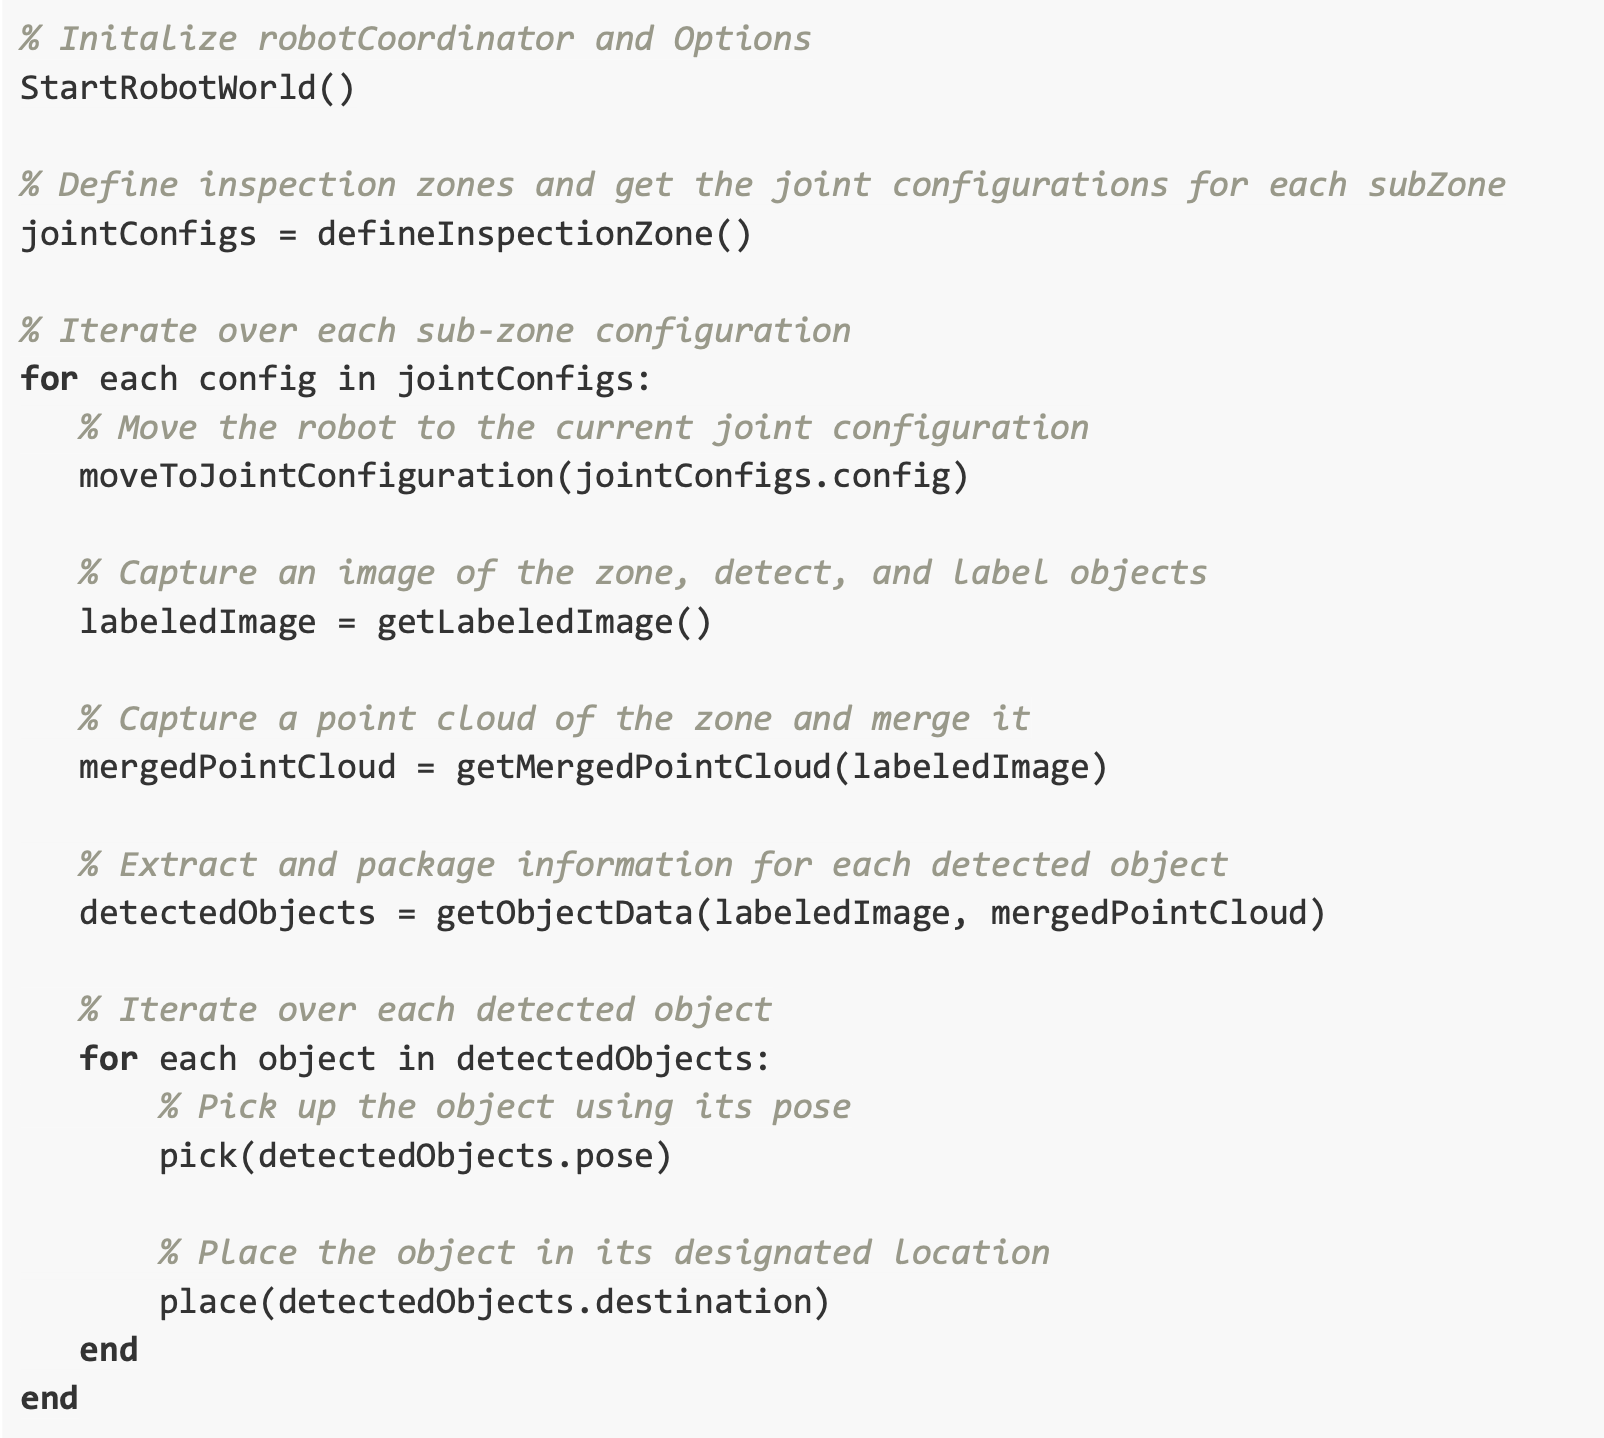

## Section 2 - Vision

Below, a high-level understanding of the vision system will be explained through the loading and manipulation of data from an actual run of the 2024 RoboCup ARM Challenge, link [here](https://www.youtube.com/watch?v=zXMk0hsVzh0&t=1928s). 

Take note of the data types and how the information is packaged to better understand the optimal way in which functions can be simply and effectively called. This section of code does not cover the robotic coordinator or options but rather skips initialization for simplification. Assume that you are in the following positions and the robot is aiming to pick and grab the objects within its view.

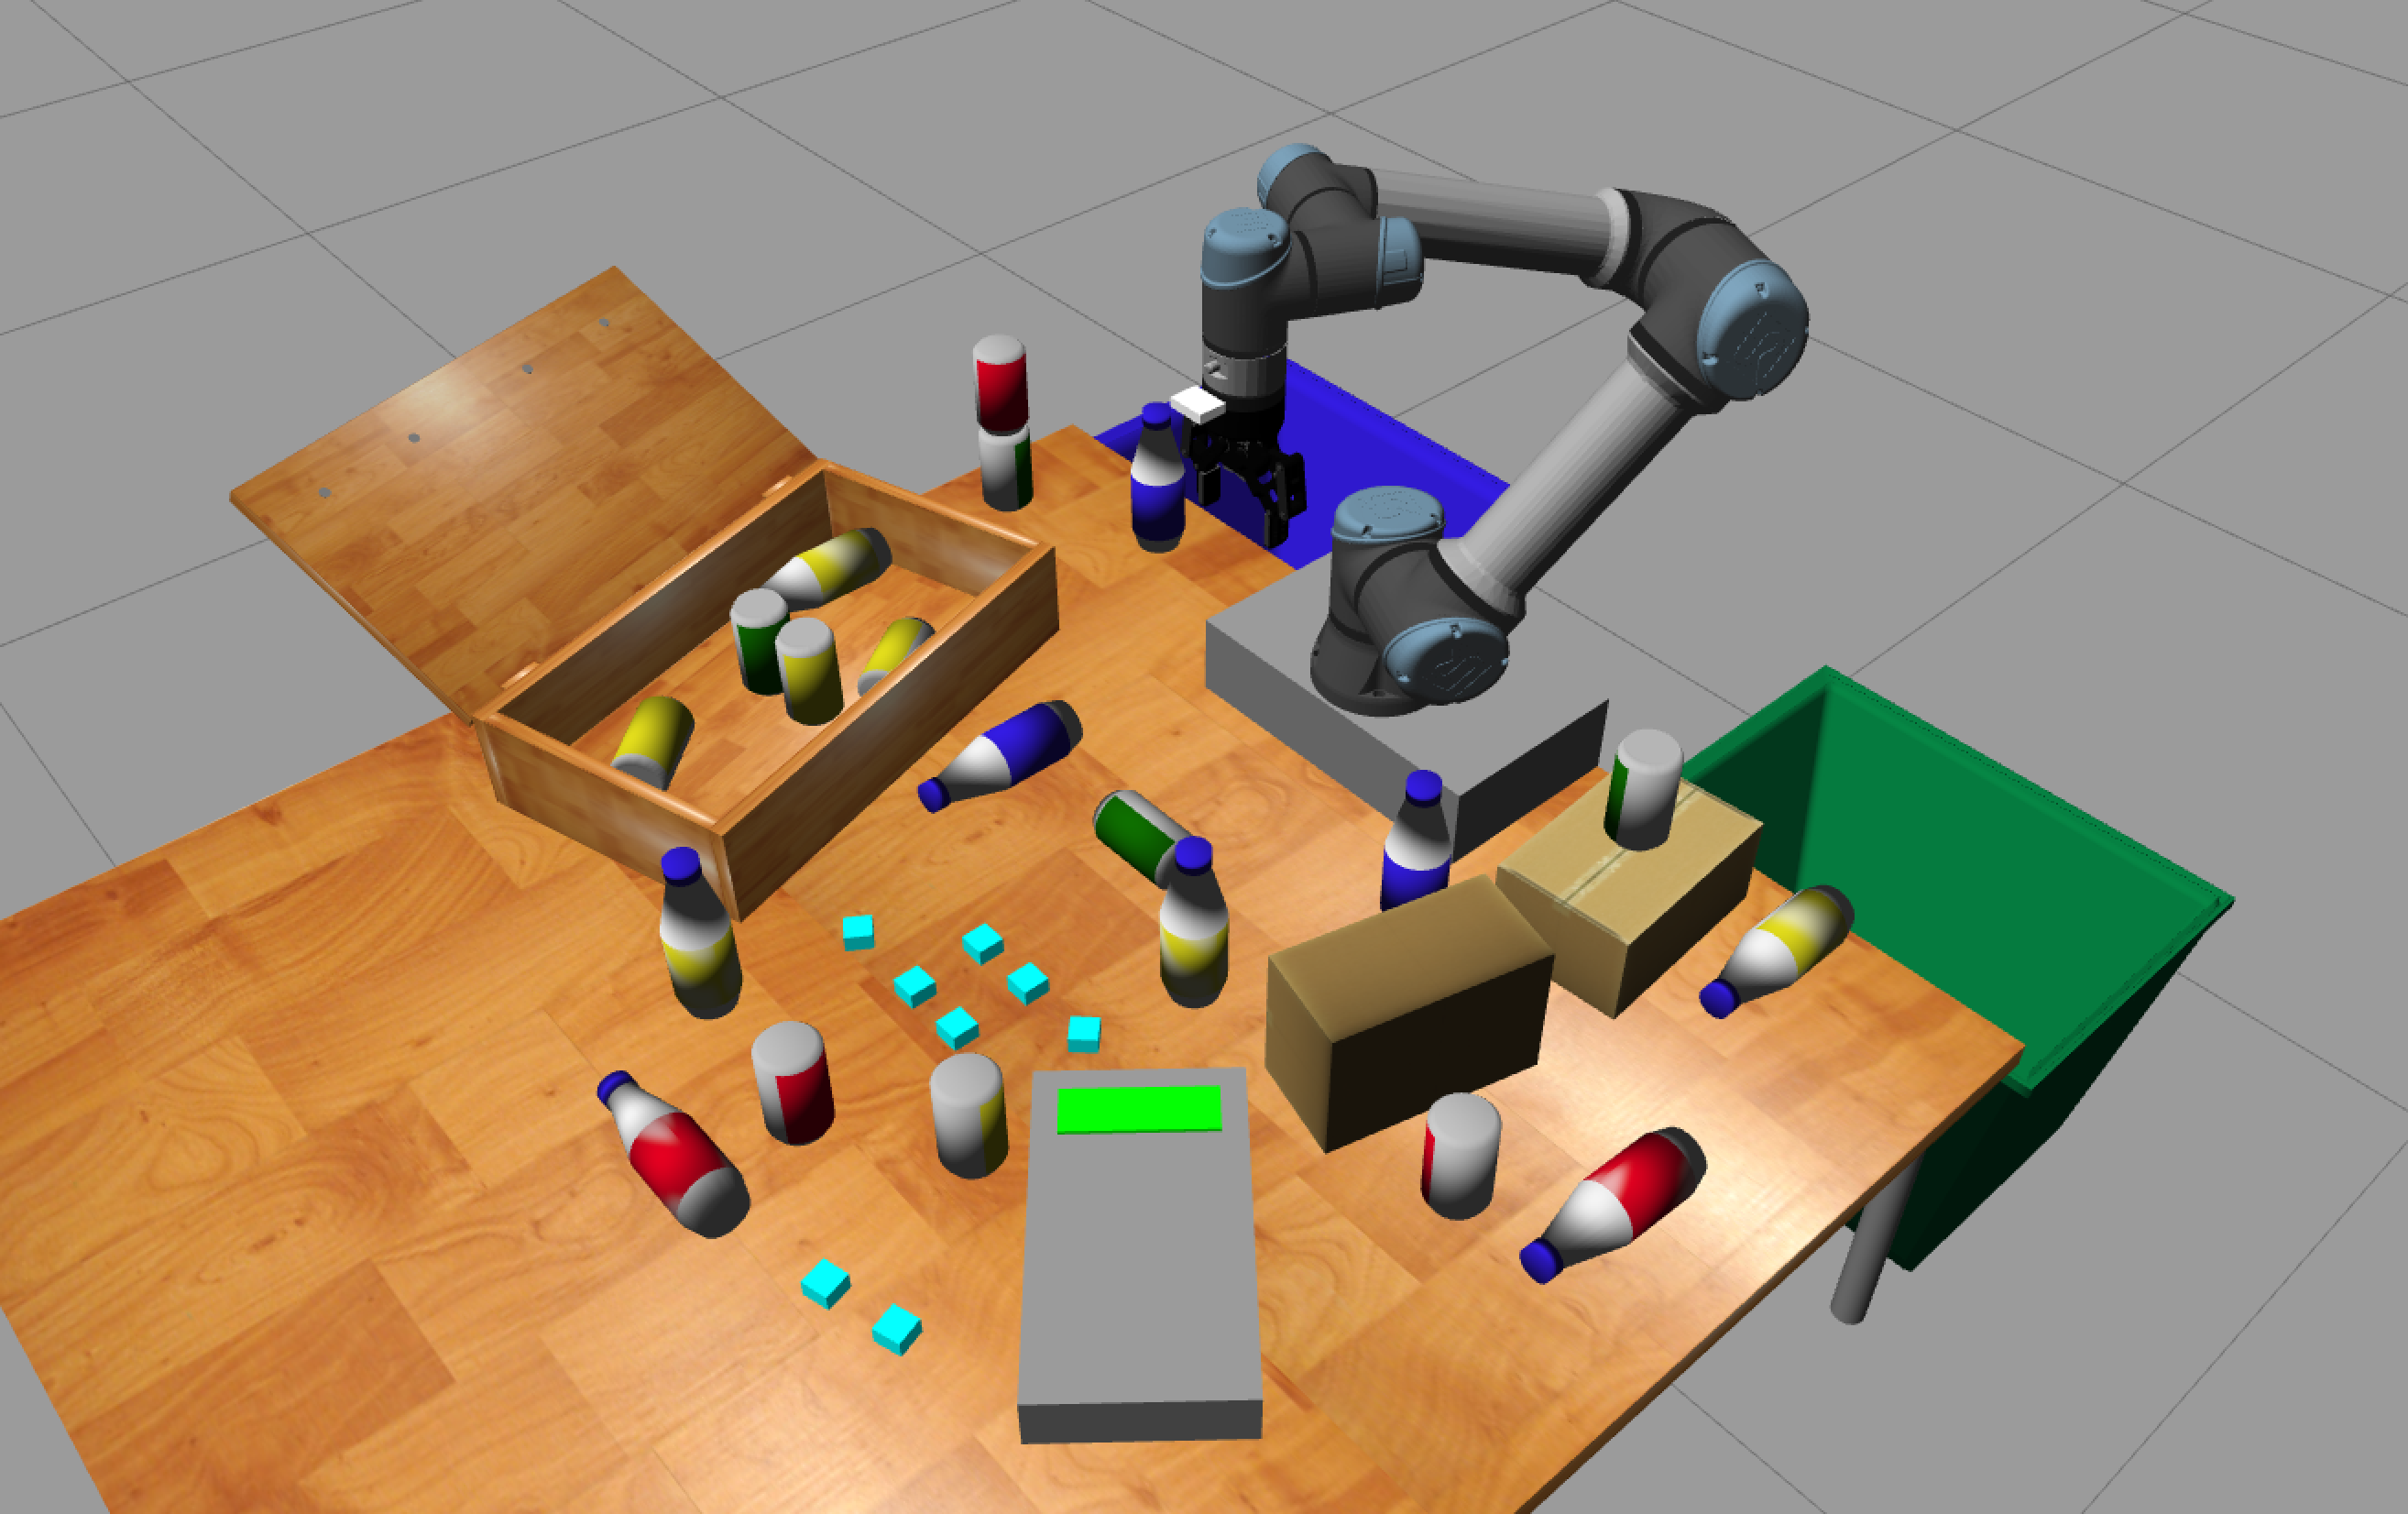

### `getLabeledImage()`

In this section, first load the required information to manipulate. You should now be able to navigate to the workspace and be given the following variables: `annotatedImage`, `bboxes`, `labeled`, `myImg`, and `numOfObjects`.

% Load the .mat file
load('example_getLabledImage.mat');

% Create a new figure for myImg and display it
figure;
imshow(myImg);
title('Camera Image');

% Create a new figure for annotatedImage and display it
figure;
imshow(annotatedImage);
title('Annotated Image');

### `getMergedPointCloud()`

In this section, you will be provided with the following information: `ptCloud_pic` and `nonPlane_pic` within the workspace.

% Load the .mat file
load('example_getMergedPointCloud.mat');

% Create a new figure for ptCloud_pic and display it
figure;
pcshow(ptCloud_pic);
title('Point Cloud Picture');

% Create a new figure for nonPlane_pic and display it
figure;
pcshow(nonPlane_pic);
title('Non-Plane Point Cloud Picture');

### `getObjectData()`

In this final section of vision, you will load `objectData`. The function will output the following information packaged within it: in the first column, the name of the object being picked will be displayed; in the second column, its corresponding pose; and finally, in the third column, the segmented point cloud information will be stored.

% Load the .mat file
load('example_getObjectData.mat');

% Display each point cloud in a separate figure
disp(objectData);
for i = 1:4
    figure;
    pcshow(objectData{i, 3});
    title(['Point Cloud Image' num2str(i)]);
end

## Section 3 - Motion Planning

Now that an initial setup has been created for visualizing and packing all the information of the objects into the variable `objectData`, let's define what motion planning is.

Motion planning is the process of determining a sequence of movements that a robot must execute to achieve a specific goal. This goal often involves navigating the robot's end effector (such as a robotic arm) from a start position to a target position while avoiding obstacles and/or optimizing certain criteria (e.g., shortest path, minimum energy consumption, obstacle avoidance).

The best way to understand motion planning is through a pipeline, a set of instructions that follow each other sequentially. The motion planning pipeline in robotics typically involves several key steps that transform a high-level task description (such as a target position and orientation in space) into specific joint configurations that the robot can use to achieve the task. Here's an overview of this process:

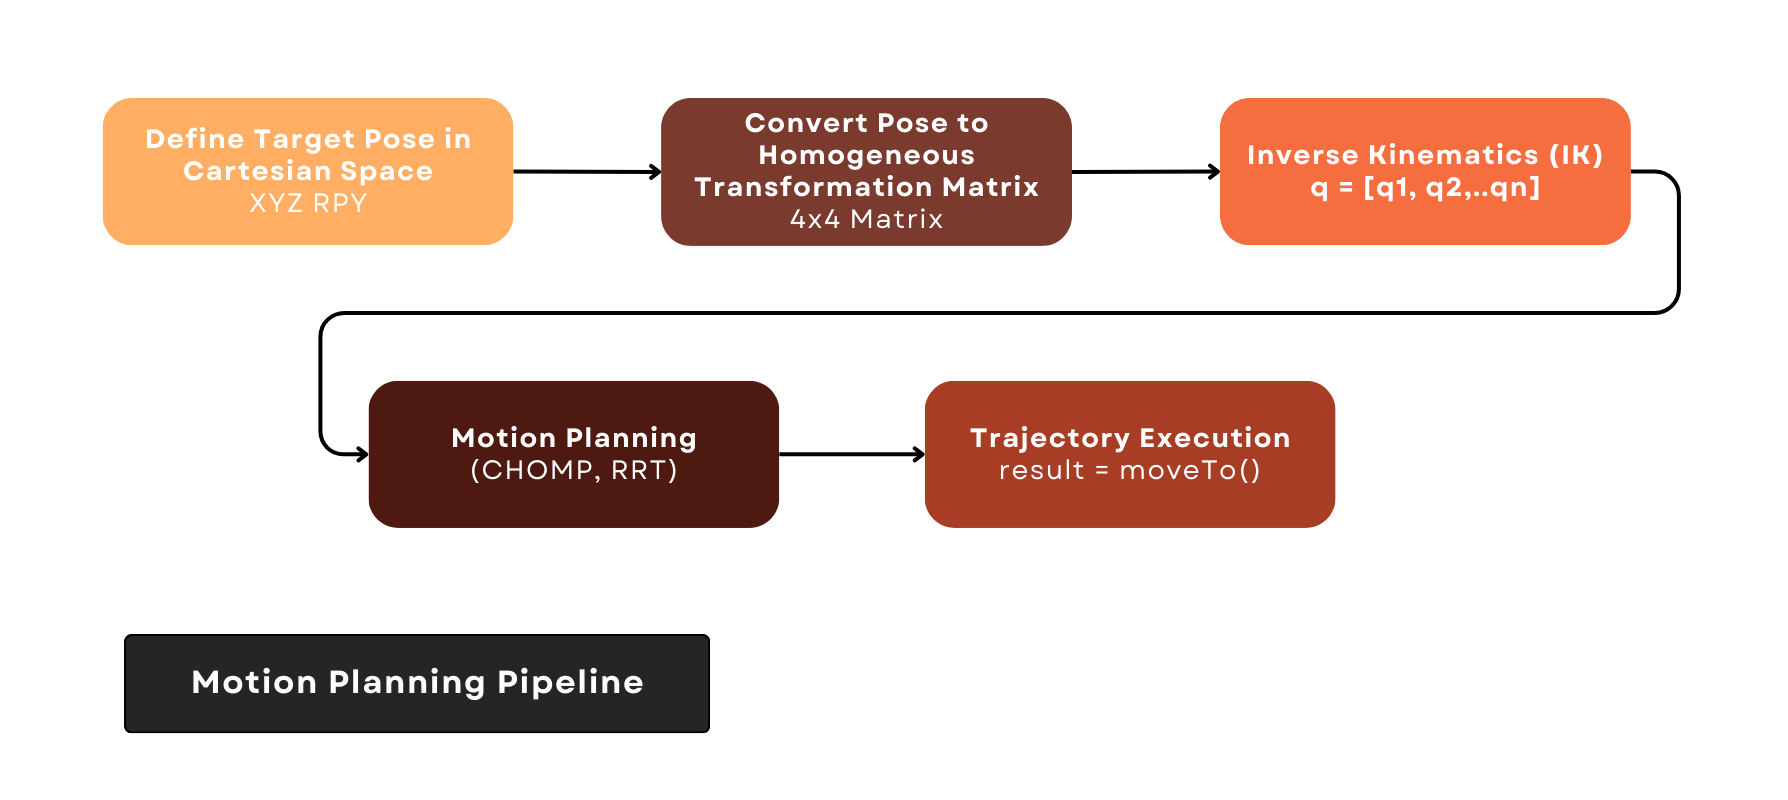

- **Define Target Pose in Cartesian Space: **The target pose is usually defined in terms of a position (x, y, z) and orientation (roll, pitch, yaw). This is often the desired position and orientation of the robot's end effector (e.g., a gripper).

- **Convert Pose to Homogeneous Transformation Matrix: **The target pose (position and orientation) is converted into a 4x4 homogeneous transformation matrix. This matrix combines both the rotation and translation into a single representation.

- **Inverse Kinematics (IK): **The transformation matrix is then used as input to an inverse kinematics (IK) solver, which computes the joint angles (or configurations) that will place the end effector at the desired pose. The IK solver takes into account the robot's kinematic chain and joint limits.

- **Motion Planning: **Once the joint angles are obtained, a motion planner can be used to generate a trajectory that the robot should follow to move from its current configuration to the desired configuration. This step ensures smooth and collision-free motion.

- **Trajectory Execution: **Finally, the planned trajectory is executed by the robot's control system, which sends the necessary commands to the robot's joints to follow the computed path.

The following is a high-level understanding of the motion planning system, walking through the steps to better understand how the robot moves. Function calls and information provided here do not require starting a virtual machine. It's essential to understand what each call does and to analyze functions such as `moveTo()`, `pick()`, and `place()` within the competition robot while keeping in mind the motion planning pipeline.

### `LoadRobot()`

First, load the robot with a start joint configuration similar to the 2024 robotics competition start configuration. Functions such as `loadRobot()` and `urdfAdjustment()` define the robot's properties such as body names, joint names, joint types, and more. Use `showdetails(robot)` after running the first line to better understand the robot's formatting, noting the datatype `1x1 rigidBodyTree`.

% Load the UR5e robot model
robot = loadrobot('universalUR5e', 'DataFormat', 'row');
robot = urdfAdjustment(robot,'UR5e',0);

% Define the initial joint configuration (all zeros)
startConfig = [0, 0, 0, 0, 0, 0];

% Show the robot model with the initial configuration
figure("Visible","on"); 
show(robot, startConfig,'PreservePlot', false, 'Frames', 'off'); hold on
axis([-1 1 -1 1 -0.5 1.2]);
view(gca,[120 20]);
title('UR5e Robot Model for Motion Planning');

### `Convert2Pose()`

Next, use the information from the vision section to create a visual representation of where each object is located. Load the variable `objectData` using `load('example_getObjectData.mat')`. Display each homogeneous transformation matrix to understand how the matrix is represented in space and why it has the orientation it does relative to the gripper arm. Ensure you comprehend the objects' poses and the direction of the xyz axes, as MATLAB and Gazebo may not always have the same reference frame. See the "Frames of Reference between Gazeebo and RVIZ.pdf" document in Canvas

% Show the "pouch" in Cartesian Space relative to Robot EndEffector
T1 = objectData{1,2};
plotTransforms(se3(T1));

% Show the "vBottle" in Cartesian Space relative to Robot EndEffector
T2 = objectData{2,2};
plotTransforms(se3(T2));

% Show the "hCan" in Cartesian Space relative to Robot EndEffector
T3 = objectData{3,2};
plotTransforms(se3(T3));

% Show the "hBottle" in Cartesian Space relative to Robot EndEffector
T4 = objectData{4,2};
plotTransforms(se3(T4));
hold off

### `inverseKinematics()`

Use the transformation matrix as input to an inverse kinematics (IK) solver to compute the joint angles. Note the datatype `RigidBodyTree` and the initial weight of joint angles guess, which can improve results since there are numerous possible joint angles for each of the UR5e robot's six joints. Providing a guess helps direct the robot's joints toward the target.

% Create an inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', robot);

% Define the weights for the IK solver (optional, but can improve results)
weights = [0.25, 0.25, 0.25, 1, 1, 1];

% Define the initial guess for the joint configuration
initialGuess = startConfig;

% Solve the IK problem for the first end-effector pose
[goalConfig1, solInfo1] = ik('tool0', T1, weights, initialGuess);
% Repeat for other end-effector poses if needed
[goalConfig2, solInfo2] = ik('tool0', T2, weights, initialGuess);
[goalConfig3, solInfo3] = ik('tool0', T3, weights, initialGuess);
[goalConfig4, solInfo4] = ik('tool0', T4, weights, initialGuess);

### `TrajectoryExecution()`

In this final section, visualize the execution of the joint trajectory. The inverse kinematics solver `ik()` only provides one joint configuration to follow to reach the desired goal. Note that this section demonstrates the pipeline used by teams to convert vision information into motion, without covering motion planning algorithms such as `CHOMP()` or `RRT() `for obstacle avoidance or minimum energy consumption. This is also done with the trajectory action server.

% Show the robot model with the computed joint configuration
figure
% First subplot
subplot(2, 2, 1);
show(robot, goalConfig1); hold on 
axis([-1 1 -1 1 -0.5 1.2]);
view(gca, [120 20]);
plotTransforms(se3(T1)); 
title('UR5e Robot Model at Goal Configuration 1'); hold off

% Second subplot
subplot(2, 2, 2);
show(robot, goalConfig2); hold on 
axis([-1 1 -1 1 -0.5 1.2]);
view(gca, [120 20]);
plotTransforms(se3(T2));
title('UR5e Robot Model at Goal Configuration 2'); hold off

% Third subplot
subplot(2, 2, 3);
show(robot, goalConfig3); hold on 
axis([-1 1 -1 1 -0.5 1.2]);
view(gca, [120 20]);
plotTransforms(se3(T3));
title('UR5e Robot Model at Goal Configuration 3'); hold off

% Fourth subplot
subplot(2, 2, 4);
show(robot, goalConfig4); hold on 
axis([-1 1 -1 1 -0.5 1.2]);
view(gca, [120 20]);
plotTransforms(se3(T4));
title('UR5e Robot Model at Goal Configuration 4'); hold off